%% Space Weather Effects on Satellite Orbit Divergence
%
% Demonstrates how real space weather data (variable solar flux F10.7 and
% geomagnetic Ap indices) causes two otherwise-identical LEO satellites to
% diverge in orbit over time.
%
%   SAT-A (Blue)  –  HPOP, NRLMSISE-00 with fixed quiet-Sun indices
%                    (F10.7 = 150, F10.7A = 150, Ap = 15)
%   SAT-B (Red)   –  HPOP, NRLMSISE-00 driven by a real space weather file
%
% Requirements
%   * MATLAB R2024b+  with  Aerospace Toolbox
%   * A space weather MAT file (see STEP 0 below)
%
% ── STEP 0:  Prepare the space weather MAT file ───────────────────────────
%
%   The propagator needs a .mat file produced by aeroReadSpaceWeatherData().
%   This function reads a CSV downloaded from CelesTrak (free, no login):
%
%     1.  Go to  https://celestrak.org/SpaceData/SW-Last5Years.csv
%         and save the file as  SW-Last5Years.csv  in your working folder.
%         (Space-Track.org also provides compatible data.)
%
%     2.  Run ONCE in the Command Window:
%           aeroReadSpaceWeatherData('SW-Last5Years.csv', ...
%               'OutputFile', 'mySpaceWeather.mat');
%
%     3.  Set WEATHER_MAT_FILE below to 'mySpaceWeather.mat'  (or the full
%         path if it lives elsewhere).
%

%% ── User Configuration ───────────────────────────────────────────────────

WEATHER_MAT_FILE = 'aerospaceweatherdata20260311.mat';   % output of aeroReadSpaceWeatherData

% Mission epoch (UTC)
missionStart = datetime(2024, 5, 10, 0, 0, 0, 'TimeZone', 'UTC');
missionDays  = 0.2;               % simulation length [days]

scenarioStep    = 60;           % satelliteScenario time step  [s]
propagatorStep  = 60;           % propagateOrbit sample cadence [s]

% Keplerian elements at epoch (J2000 GCRF)
sma  = 6778e3;   % semi-major axis [m]  (~400 km altitude)
ecc  = 0.001;    % eccentricity
inc  = 51.6;     % inclination        [deg]
raan = 45.0;     % RAAN               [deg]
argp = 0.0;      % argument of periapsis [deg]
nu0  = 0.0;      % true anomaly at epoch [deg]

% Spacecraft physical properties (identical for both satellites)
mass  = 500;     % [kg]
dragA = 3.0;     % drag area  [m^2]
cd    = 2.2;     % drag coefficient
srpA  = 3.0;     % SRP area   [m^2]
cr    = 1.8;     % reflectivity coefficient

%% ── 1.  Time Vector ──────────────────────────────────────────────────────

missionEnd = missionStart + days(missionDays);
t = missionStart : seconds(propagatorStep) : missionEnd;

fprintf('Mission:  %s  ->  %s\n', missionStart, missionEnd);

Mission:  10-May-2024  ->  10-May-2024 04:48:00


fprintf('Steps:    %d   (%.0f s cadence)\n\n', numel(t), propagatorStep);

Steps:    289   (60 s cadence)




%% ── 2.  Physical Properties (shared) ────────────────────────────────────

physProps = Aero.spacecraft.PhysicalProperties( ...
    Mass                         = mass, ...
    DragArea                     = dragA, ...
    DragCoefficient              = cd, ...
    SRPArea        = srpA, ...
    ReflectivityCoefficient = cr);

%% ── 3.  Numerical Propagator Options ─────────────────────────────────────
%
% The space weather input MUST be a pre-processed .mat file, not a raw CSV.
% Generate it once with: aeroReadSpaceWeatherData('SW-Last5Years.csv', ...)

odesOpts = odeset('RelTol', 1e-10, 'AbsTol', 1e-12);

% ── SAT-A: fixed / quiet-Sun density (no space weather file) ─────────────
numericsA = Aero.spacecraft.NumericalPropagatorOptions( ...
    ODESet                      = odesOpts, ...
    GravitationalPotentialModel = "spherical-harmonics", ...
    SphericalHarmonicModel      = "EGM96", ...
    SphericalHarmonicDegree     = 70, ...
    IncludeAtmosDrag            = true, ...
    UseSpaceWeatherDataFile     = false, ...   % fixed indices
    F107Average                 = 150, ...     % quiet-Sun 81-day avg
    F107Daily                   = 150, ...     % quiet-Sun daily flux
    MagneticIndex               = 15, ...      % quiet geomagnetic Ap
    IncludeThirdBodyGravity     = true, ...
    ThirdBodyGravitySource      = ["Sun", "Moon"], ...
    IncludeSRP                  = true);

% ── SAT-B: real space weather data file drives NRLMSISE-00 ───────────────
if ~isfile(WEATHER_MAT_FILE)
    warning(['Space weather MAT file ''%s'' not found.\n' ...
        'SAT-B will use the same fixed indices as SAT-A (no divergence).\n' ...
        'See STEP 0 in the script header to generate the MAT file.\n'], ...
        WEATHER_MAT_FILE);
    numericsB = numericsA;     % graceful fallback
else
    numericsB = Aero.spacecraft.NumericalPropagatorOptions( ...
        ODESet                      = odesOpts, ...
        GravitationalPotentialModel = "spherical-harmonics", ...
        SphericalHarmonicModel      = "EGM96", ...
        SphericalHarmonicDegree     = 70, ...
        IncludeAtmosDrag            = true, ...
        UseSpaceWeatherDataFile     = true, ...    % real data
        SpaceWeatherDataFile        = WEATHER_MAT_FILE, ...
        F107ExtrapMethod            = "none-clip", ...
        MagneticIndexExtrapMethod   = "none-clip", ...
        IncludeThirdBodyGravity     = true, ...
        ThirdBodyGravitySource      = ["Sun", "Moon"], ...
        IncludeSRP                  = true);
end

%% ── 4.  Propagate Both Orbits ────────────────────────────────────────────

fprintf('Propagating SAT-A (fixed quiet-Sun density)...\n');

Propagating SAT-A (fixed quiet-Sun density)...


[posA, velA] = propagateOrbit(t, sma, ecc, inc, raan, argp, nu0, ...
    PropModel                  = "numerical", ...
    NumericalPropagatorOptions = numericsA, ...
    PhysicalProperties         = physProps, ...
    Epoch                      = missionStart, ...
    OutputCoordinateFrame      = "inertial");

fprintf('Propagating SAT-B (space-weather density)...\n');

Propagating SAT-B (space-weather density)...


[posB, velB] = propagateOrbit(t, sma, ecc, inc, raan, argp, nu0, ...
    PropModel                  = "numerical", ...
    NumericalPropagatorOptions = numericsB, ...
    PhysicalProperties         = physProps, ...
    Epoch                      = missionStart, ...
    OutputCoordinateFrame      = "inertial");

fprintf('Propagation complete.\n\n');

Propagation complete.




%% ── 5.  Pack into Timetables ─────────────────────────────────────────────
%
% satellite() with 'CoordinateFrame','ICRF' accepts timetables of [x y z]
% in meters with absolute datetime row-times.  Supplying velocity improves
% makima interpolation accuracy inside the scenario viewer.

ttPosA = timetable(t', posA');
ttVelA = timetable(t', velA');

ttPosB = timetable(t', posB');
ttVelB = timetable(t', velB');

%% ── 6.  Build Satellite Scenario ─────────────────────────────────────────

sc = satelliteScenario(missionStart, missionEnd, scenarioStep);

satA = satellite(sc, ttPosA, ttVelA, ...
    'Name', 'SAT-A  Fixed Density');

satB = satellite(sc, ttPosB, ttVelB, ...
    'CoordinateFrame', 'inertial', ...
    'Name', 'SAT-B  Space Weather');

%% ── 7.  Styling ──────────────────────────────────────────────────────────

satA.MarkerColor     = [0.20 0.45 0.90];   % blue
satA.Orbit.LineColor = [0.20 0.45 0.90];
satA.Orbit.LineWidth = 1.5;

satB.MarkerColor     = [0.90 0.20 0.20];   % red
satB.Orbit.LineColor = [0.90 0.20 0.20];
satB.Orbit.LineWidth = 1.5;


%% ── 8.  Open Viewer ──────────────────────────────────────────────────────

v = satelliteScenarioViewer(sc, 'ShowDetails', true);
v.PlaybackSpeedMultiplier = 1000;
camtarget(v, satA);

% Uncomment to start playback immediately:
% play(sc);

fprintf('Viewer open.\n');

Viewer open.


fprintf('  Blue = SAT-A  (fixed quiet-Sun  F10.7=150, Ap=15)\n');

  Blue = SAT-A  (fixed quiet-Sun  F10.7=150, Ap=15)


fprintf('  Red  = SAT-B  (real space weather from %s)\n\n', WEATHER_MAT_FILE);

  Red  = SAT-B  (real space weather from aerospaceweatherdata20260311.mat)



fprintf('Press Play in the viewer toolbar to run the simulation.\n\n');

Press Play in the viewer toolbar to run the simulation.



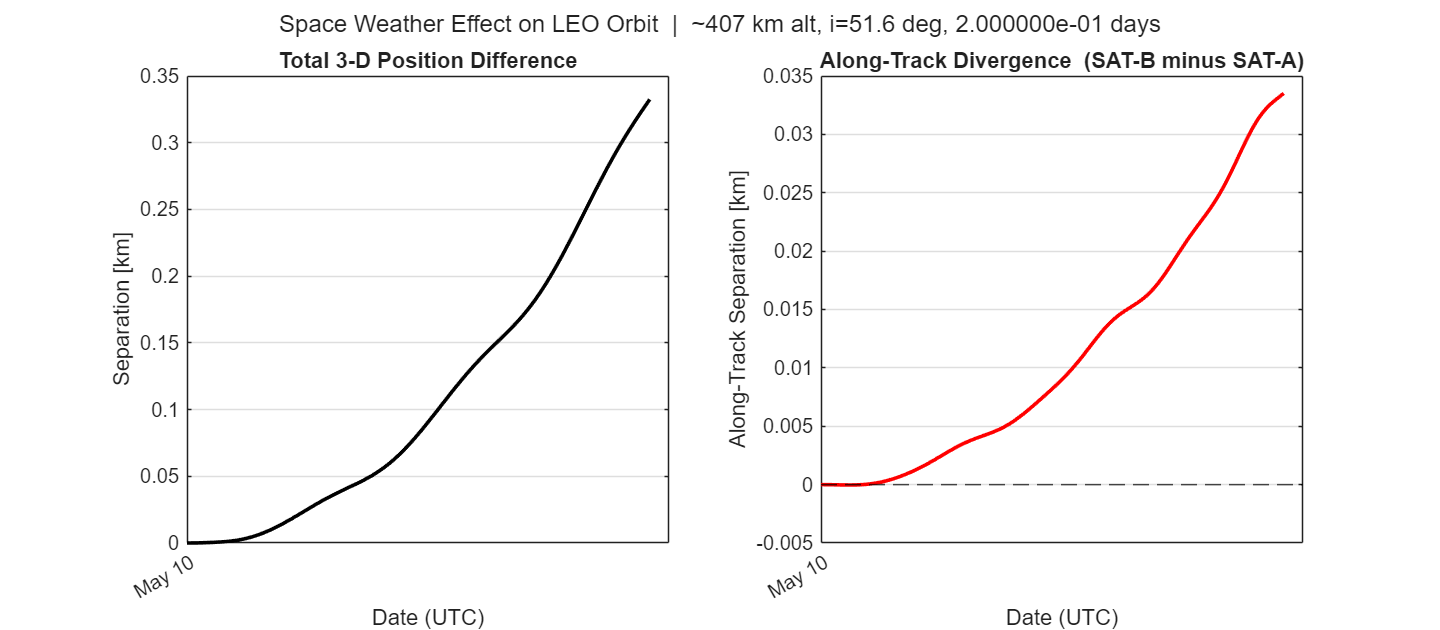

hide(satA.Orbit);
hide(satB.Orbit);

%% ── 9.  Divergence Analysis Plot ─────────────────────────────────────────

deltaPos   = posB' - posA';                            % [Nx3] m
totalSep   = vecnorm(deltaPos, 2, 2) / 1e3;          % total separation [km]

vA_hat     = velA ./ vecnorm(velA, 2, 2);            % along-track unit vector
alongTrack = dot(deltaPos, vA_hat', 2) / 1e3;         % signed along-track [km]

figure('Name','Orbit Divergence - Space Weather Effect', ...
       'NumberTitle','off','Position',[100 100 960 420]);

subplot(1,2,1)
plot(t, totalSep, 'k-', 'LineWidth', 1.8)
xlabel('Date (UTC)');  ylabel('Separation [km]')
title('Total 3-D Position Difference')
grid on;  datetick('x','mmm dd','keeplimits');  xtickangle(30)

subplot(1,2,2)
plot(t, alongTrack, 'r-', 'LineWidth', 1.8)
yline(0,'--k','LineWidth',0.8)
xlabel('Date (UTC)');  ylabel('Along-Track Separation [km]')
title('Along-Track Divergence  (SAT-B minus SAT-A)')
grid on;  datetick('x','mmm dd','keeplimits');  xtickangle(30)

sgtitle(sprintf('Space Weather Effect on LEO Orbit  |  ~%.0f km alt, i=%.1f deg, %d days', ...
    (sma/1e3 - 6371), inc, missionDays), 'FontSize', 12)


fprintf('Peak total separation    : %8.3f km\n', max(totalSep));

Peak total separation    :    0.332 km


fprintf('Peak along-track offset  : %8.3f km\n', max(abs(alongTrack)));

Peak along-track offset  :    0.034 km
